tic
u=[0:1:5]; %vary u from 0 to 1000 also
figure1=figure('Position',[100,100,7000,10000])

figure1 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [100 100 7000 10000]
       Units: 'pixels'

  Show all properties


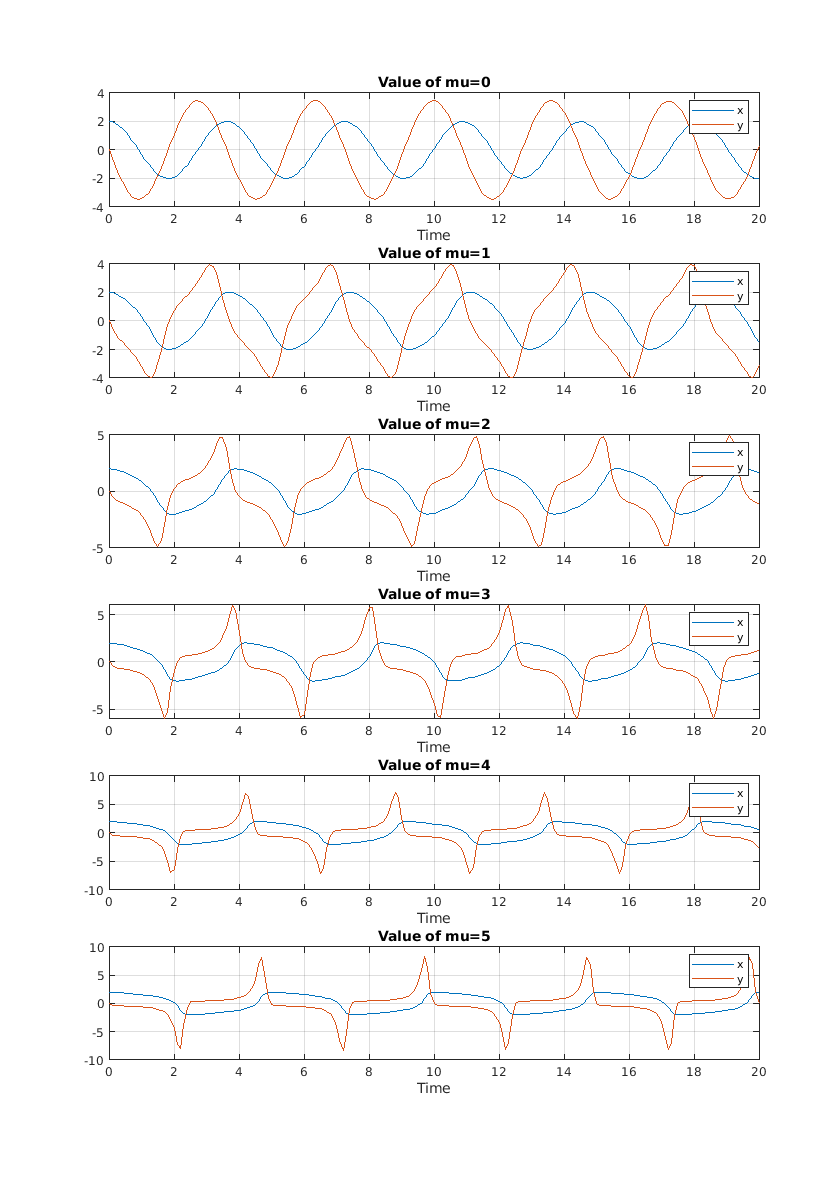

for j=1:length(u)
f = @(x,y) y;
g = @(x,y) u(j)*(1-x^2)*y-3*x;
t=[0:0.1:20]';
l=length(t);
x=zeros(l,2);
x(1,1)=2;
x(1,2)=0;
h=0.1;

for i=1:l-1
    k1=zeros(1,2);
    k2=zeros(1,2);
    k3=zeros(1,2);
    k1(1,1) = f(x(i,1),x(i,2));
    k1(1,2) = g(x(i,1),x(i,2));
    
    k2(1,1) = f(x(i,1)+h*k1(1,1)/2, x(i,2)+h*k1(1,2)/2);
    k2(1,2) = g(x(i,1)+h*k1(1,1)/2, x(i,2)+h*k1(1,2)/2);
    
    
    k3(1,1) = f(x(i,1)-h*k1(1,1)+2*h*k2(1,1),x(i,2)-h*k1(1,2)+2*h*k2(1,2));
    k3(1,2) = g(x(i,1)-h*k1(1,1)+2*h*k2(1,1),x(i,2)-h*k1(1,2)+2*h*k2(1,2));
    x(i+1,:) = x(i,:) + (h/6)*(k1+4*k2+k3);
end

subplot(6,1,j)
plot(t,x)
title("Value of mu="+u(j))
legend('x','y');
xlabel('Time')
grid()

end

timetaken_param_vary=toc

timetaken_param_vary = 0.6269